## Question 2

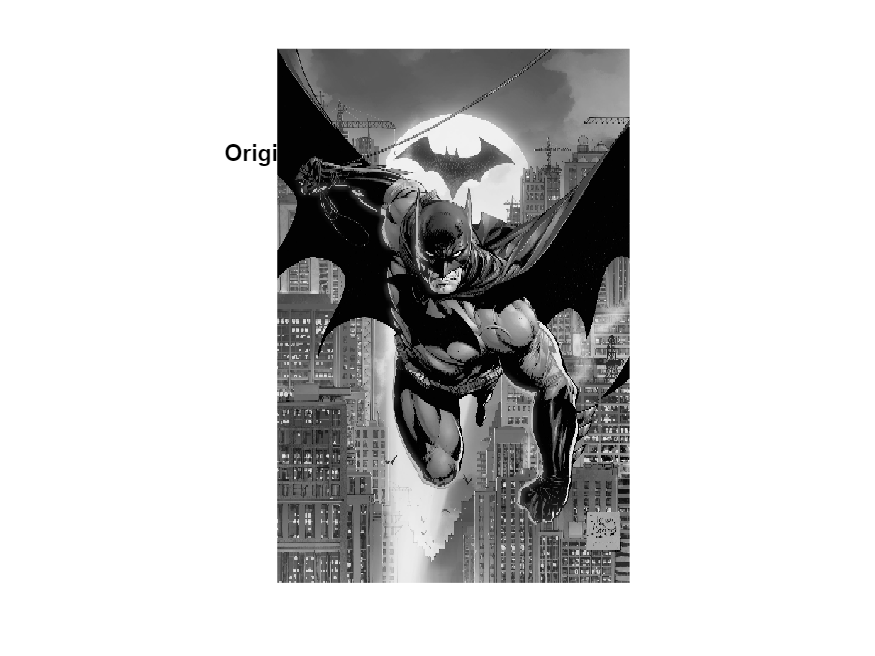

img = imread('Bat.jpg');
gray_img = rgb2gray(img);
gray_img = im2double(gray_img); 

floyd_steinberg = [0 0 7; 3 5 1] / 16;
jarvis_judice_ninke = [0 0 0 7 5; 3 5 7 5 3; 1 3 5 3 1] / 48;

floyd_img = ditheringAlgorithm(gray_img, floyd_steinberg);
jarvis_img = ditheringAlgorithm(gray_img, jarvis_judice_ninke);

figure, imshow(gray_img), title('Original Grayscale Image');

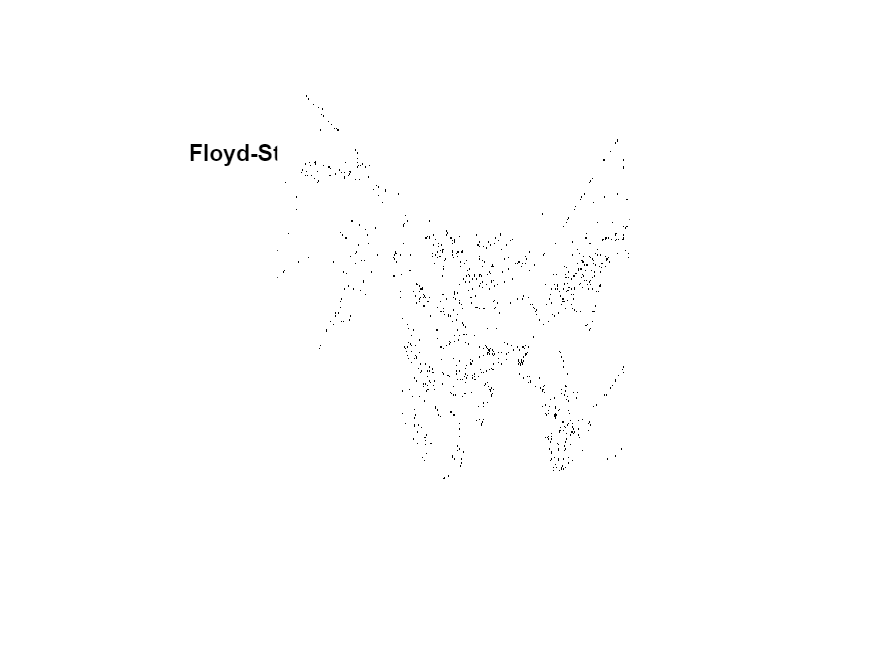

figure, imshow(floyd_img), title('Floyd-Steinberg Dithered Image');

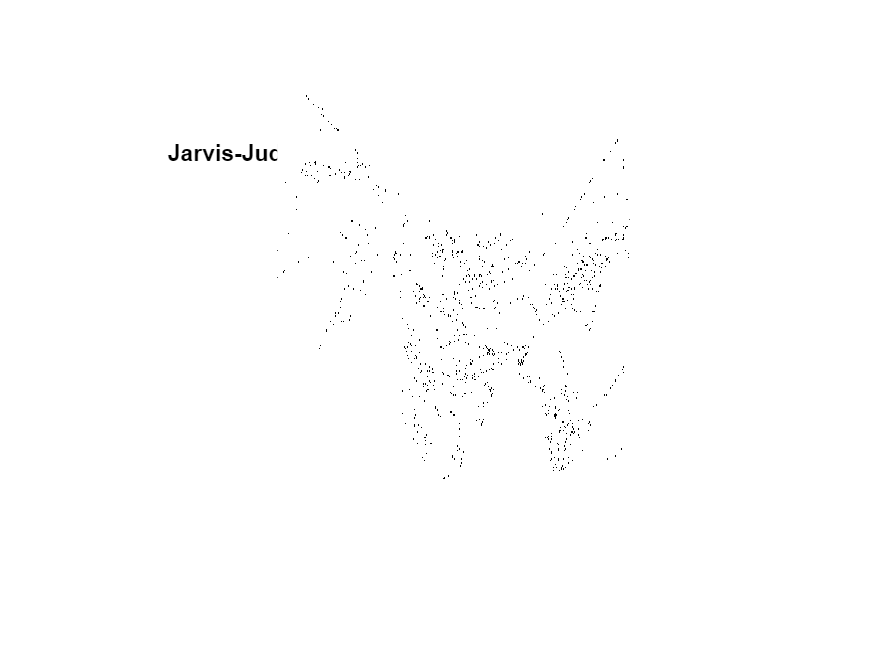

figure, imshow(jarvis_img), title('Jarvis-Judice-Ninke Dithered Image');

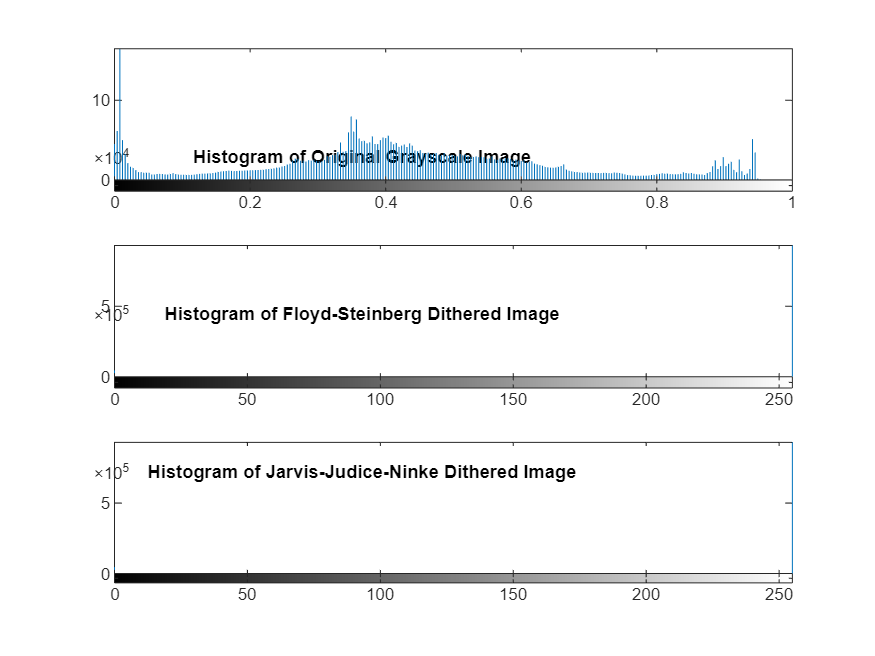

figure;
subplot(3,1,1), imhist(gray_img), title('Histogram of Original Grayscale Image');
subplot(3,1,2), imhist(floyd_img), title('Histogram of Floyd-Steinberg Dithered Image');
subplot(3,1,3), imhist(jarvis_img), title('Histogram of Jarvis-Judice-Ninke Dithered Image');

disp('Explanation and Observations:');

Explanation and Observations:


disp('The Floyd-Steinberg dithering uses a 4-neighbor diffusion matrix and is primarily used for monochrome printers. The error is propagated to the neighboring pixels that are yet to be processed. This method is sensitive to the ordering of pixels.');

The Floyd-Steinberg dithering uses a 4-neighbor diffusion matrix and is primarily used for monochrome printers. The error is propagated to the neighboring pixels that are yet to be processed. This method is sensitive to the ordering of pixels.


disp('The Jarvis-Judice-Ninke dithering, on the other hand, uses a larger diffusion matrix with more neighbors, thus it tends to provide a smoother gradient in the dithered output at the cost of higher computational expense. It is effective for images with gradual tonal changes.');

The Jarvis-Judice-Ninke dithering, on the other hand, uses a larger diffusion matrix with more neighbors, thus it tends to provide a smoother gradient in the dithered output at the cost of higher computational expense. It is effective for images with gradual tonal changes.


disp('Both dithering techniques alter the image by distributing quantization errors across neighboring pixels, thereby reducing the appearance of quantization errors and improving the visual quality of the dithered images. The histograms demonstrate the redistribution of pixel intensities due to each method.');

Both dithering techniques alter the image by distributing quantization errors across neighboring pixels, thereby reducing the appearance of quantization errors and improving the visual quality of the dithered images. The histograms demonstrate the redistribution of pixel intensities due to each method.


disp('Numerical histogram values for both dithering techniques would further quantify the changes in pixel distribution and help in assessing the effectiveness of each dithering approach in different scenarios.');

Numerical histogram values for both dithering techniques would further quantify the changes in pixel distribution and help in assessing the effectiveness of each dithering approach in different scenarios.


% Function to apply dithering based on input image and dither matrix
function output = ditheringAlgorithm(img, matrix)
    [rows, cols] = size(img);
    output = zeros(rows, cols); 
    for i = 1:rows
        for j = 1:cols
            old_pixel = img(i, j);
            new_pixel = round(255 * old_pixel);
            output(i, j) = new_pixel;
            error = old_pixel - new_pixel/255;
            [mat_rows, mat_cols] = size(matrix);
            for x = 1:mat_rows
                for y = 1:mat_cols
                    ix = i + x - 2;  
                    jy = j + y - 2 - floor(mat_cols/2);
                    if ix > 0 && ix <= rows && jy > 0 && jy <= cols
                        output(ix, jy) = output(ix, jy) + error * matrix(x, y);
                    end
                end
            end
        end
    end
    output = uint8(output * 255);  
end